# Diffusion model 3D

### 1-3. Create PDE, geometry and Mesh

% 1. create pde system
model = createpde;

% 2. Import CAD geometry
g1 = importGeometry(model,'Breast_tumor.stl');
rotate(g1,90,[0 -40 0],[0 40 0])

ans =   DiscreteGeometry with properties:

       NumCells: 2
       NumFaces: 3
       NumEdges: 5
    NumVertices: 9
       Vertices: [9×3 double]


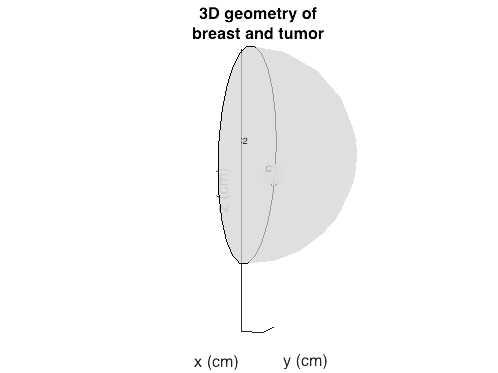

figure(10);
%subplot(1,2,1)

pdegplot(model,'FaceLabels','off','CellLabels','on','FaceAlpha',0.7);
xlabel('x (cm)','FontSize',18)
ylabel('y (cm)','FontSize',18)
zlabel('z (cm)','FontSize',18)
xlim([0 10])
ylim([-10 10])
title(["3D geometry of","breast and tumor"],'FontSize',18) 
set(gca,'XTick', [],'YTick',[],'ZTick',[])
view([15.4143720954934 7.23870967741936])

%set(gca,'XTick', -10:50:50,'YTick',-50:100:50,'ZTick',-50:100:50)
%subplot(1,2,2)
%pdegplot(model,'CellLabels','on','FaceAlpha',0.2);

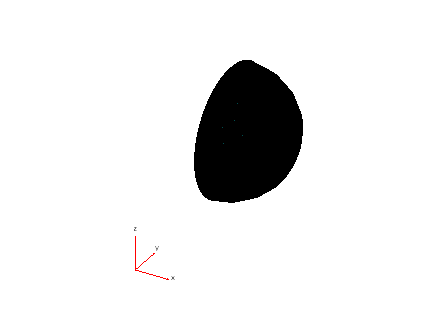


% 3. create mesh 
mesh2 = generateMesh(model,'GeometricOrder','linear','Hmax',1); %Hmin defines a lighter model, less detailed while Hmax increases the level of analysis
figure(11)
pdemesh(model,'FaceAlpha',0.3);


mesh2.Nodes(:,5); % nodes: [3xiiii]

### 4-6. define BC, IC and properties

% 4. Boundary conditions 
% are either Neumann ('g') = flux across the boundaries + 'q' = convective
% flux % if not defined = 0
%or Dirichlet ('u') = surfaces held at fixed concentration/temperatures
flux_out = 0; % mass flux = [mol/m2*s]   % randomly chosen ?
flux_body = 50 ; % constant concentration of NPs in rest of body (mg/mL) --> later specify decrease

% breast: 1. outside, 2. attached to body
applyBoundaryCondition(model,'neumann','face',2,'q',0,'g',flux_out); % 'face' 2 for 3-D % 20 degrees
applyBoundaryCondition(model,'neumann','face',3,'q',0,'g',@myfunc2); % 'face' 2 for 3-D % 20 degrees

% 5. Initial condition
% find out if time dependent or not: if not --> elliptic eq.
                                    % if    --> parabolic eq.

SourceValue = 3.19*10^20; % #/cm3concentration of NPs per injection volume ~1.25E+12 #NPs/injection
PointSources = [10 10 -10;
                7 7 -7;
                12 12 -12;
                11 6 -6;
                6 6 -11;
                9 8 8];
x0 = PointSources(:,1); 
y0 = PointSources(:,2); 
z0 = PointSources(:,3); 
sigmax = 0.2;           % standard deviation: smaller --> smaller negative concentration  
sigmay = 0.2;          % ?? --> smaller value larger negative concentration
sigmaz = 0.2;          % ?? --> smaller value larger negative concentration

Cini1 = 0; % mg/ml = kg/m3: initial concentration of NPs in body
C_NP0 = @(location)Cinit_NP3D(location,x0,y0,z0,sigmax,sigmay,sigmaz,SourceValue); % mg/ml = kg/m3: concentration of NPs in seeds
setInitialConditions(model,Cini1);
setInitialConditions(model,C_NP0,'Cell',1);

% 5. put in properties
% specify the coefficients for Poissons equation in the model
% m * d2u/dt2 + d * du/dt - nabla(c*nabla(u) + a * u )= f
%possible to define per face or per cell the physical properties
%breast 
f_b = 0; % R_A = reaction rate / mass generation = 0
a_b = 0; % convective flux % rho*Cp*v = a = 0
c_b = 1.63*10^(-9)*60*60; % c = D = diffusion coefficient % approximately body
d_b = 1; % 0 of time independent % d = 1 if time dependent
specifyCoefficients(model,'Cell',2,'m',0,'d',d_b,'c',c_b,'a',a_b,'f',f_b);

% tumor
f_t = 0; % R_A = reaction rate / mass generation = 0
a_t = 0; % convective flux % rho*Cp*v = a = 0
c_t = 1.052*10^(-9)*60*60; % c = D = [m2/s] diffusion coefficient % approximately body
d_t = 1; % 0 of time independent % d = 1 if time dependent
specifyCoefficients(model,'Cell',1,'m',0,'d',d_t,'c',c_t,'a',a_t,'f',f_t);

% time scale
h = 24; % number of hours
tlist = 0:1:h; % times at which to compute a solution specified in the array tlist
                    % between 0 and 60 minutes in steps of 60 secs

### 6. solve PDE system

results = solvepde(model,tlist);
T = results.NodalSolution;
solMax = max(results.NodalSolution);

% T(:,2)
% T_check = T(:,2) > 1800;
% T_check2 = sum(T_check(:) == 1)
% C = maxk(T(:,61),40)
% 
% elemPS = findElements(mesh2,'radius',PointSources(1,:),3) 
% for i = 1:length(elemPS) 
%     nodePS = findElements(mesh2,'attached',elemPS(1,i)) 
% end
% nodePS = findNodes(mesh2,'nearest',PointSources(1,:)')
% elemPS = findElements(mesh2,'attached',nodePS)
% 
% figure
% plot(mesh2.Nodes(1,nodePS),mesh2.Nodes(2,nodePS),'or','Color','r', ...
%                                            'MarkerFaceColor','r')
% hold on
% pdemesh(mesh2.Nodes,mesh2.Elements(:,elemPS),'EdgeColor','green','FaceAlpha',0.3)
% %% find mesh elements for Point source coordinates
% for i = 1:nPointSources
%     nodePS = zeros(nPointSources, 1)
%     nodePS(i,1) = findNodes(mesh2,'nearest',PointSources(1,:)')
%     elemPS = zeros(nPointSources, 100);
%     elemPS(i,1:length) = findElements(mesh2,'attached',nodePS(i,1))
% end
% 
% figure
% plot(mesh2.Nodes(1,nodePS),mesh2.Nodes(2,nodePS),'or','Color','r', ...
%                                            'MarkerFaceColor','r')
% hold on
% pdemesh(mesh2.Nodes,mesh2.Elements(:,elemPS),'EdgeColor','green','FaceAlpha',0.3)
% C = maxk(T,1)
% pdeplot3D(model,"ColormapData",T,"FaceAlpha",0.2)
% clim([0 C])

## Diffusion plots over time

% for i = 0:4
%     for j = 1:4 
%         figure(i+1);
%         subplot(2,2,j);
%         pdeplot3D(model,"ColorMapData",T(:,((1+(j-1)+(4*i)))),'FaceAlpha',0.1);
%         xlim([0 20]);
%         ylim([0 20]);
%         zlim([-20 0]);
%         caxis([0 C(1,1)]);
%         title(['Temperature at time =', num2str((1+(j-1)+(4*i))*3*min),' min'])
%         axis on
%     end
% end

## Two diffusion plots in time

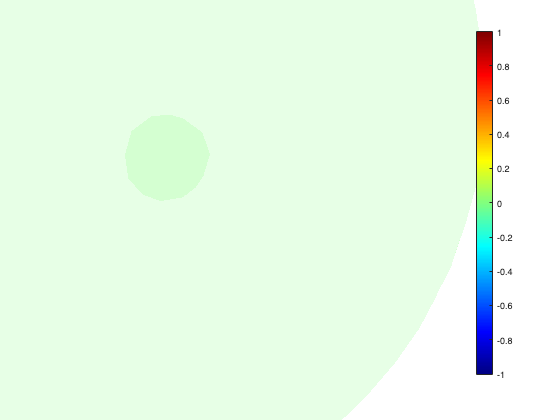

a = 4;
figure(12);
%subplot(2,2,j);
pdeplot3D(model,"ColorMapData",T(:,a),'FaceAlpha',0.1);
xlim([5 30]);
ylim([5 30]);
zlim([-30 -5]);

caxis([0 solMax(end)]);

Unrecognized function or variable 'C'.

axis on

figure(13);
%subplot(2,2,j);
pdeplot3D(model,"ColorMapData",T(:,a+1),'FaceAlpha',0.1);
xlim([5 30]);
ylim([5 30]);
zlim([-30 -5]);
caxis([0 solMax(end)]);
axis on

### Initial condition function

function Cinit_tumor = Cinit_NP3D(location,x0,y0,z0,sigmax,sigmay,sigmaz,SourceValue)
        % heaviside gives 0 if the equation of radius - the circle is smaller than 0 (location is outside the circle)
        % and gives 1*Sourcevalue for all locations within the circle
        % third term represents a normal distribution over x and y, resulting in a smooth distribution
        % with the coordinations of the node as the maximum of the Gaussian peak (=1).
        % This needs to be multiplied with the value of the concentration of the injection
        Cinit_tumor = 0;
        for i = 1:length(x0)
        Cinit_seed = (heaviside(0.5- ( (location.x-x0(i)).^2 + (location.y-y0(i)).^2 + (location.z-z0(i)).^2) ) ) .*SourceValue .*exp( -( (location.x-x0(i)).^2 ./ sigmax^2 ) -( (location.y-y0(i)).^2 ./ sigmay^2) -( (location.z-z0(i)).^2 ./ sigmaz^2) ); 
        Cinit_tumor = Cinit_tumor + Cinit_seed;
        end        
end

function bcbreast = myfunc2(~,state)        % function for boundary condition at body
    bcbreast = state.u*1.63*10^(-8)*60*60;  % cm2/h
end


% function fcoef_tumor = fcoef_PS(location,~,nPointSources,PointSources,SourceValue)
% 
% fcoef_tumor = zeros(1,length(location.x));
%     for l = 1:nPointSources
%         for i = 1:numel(fcoef_tumor) 
%                 if location.x == PointSources(l,1) & location.y == PointSources(l,2) & location.z == PointSources(l,3)
%                     indexX = find(location.x(:) == PointSources(l,1));
%                     indexY = find(location.y(:) == PointSources(l,2));
%                     indexZ = find(location.z(:) == PointSources(l,3));
%                     indicesXY = intersect(indexX,indexY);
%                     indicesXYZ = intersect(indicesXY,indexZ);
%                     fcoef_tumor(1,indicesXYZ) = SourceValue;
%                 end
%         end
%     end
%     fcoef_tumor
% end
% 